## Pretty Maps and PPS

This excercise has two parts. The first is short and about making maps. The second part is optional and introduces the newest TT object: Point-patterns on stream networks, short PPS.

Calculating lots of metrics is fun but at the end of the day you gotta export your map and probably want some publication ready figures. So let's explore what TT has to offer in terms of map/figure making for publication. The obvious benefit of this is, that if you change something about your input data, you just need to hit the run button for updating your figure.

clc
clear 
close all
DEM = GRIDobj('Hartz_utm.tif');  % load DEM

Let's calculate the flow direction and stream network. If you don't remember how look back to the older practicals. 

FD  = FLOWobj(DEM,'preprocess','carve');
DEM = imposemin(FD,DEM); % imposes minimum gradient downstream for rivers, very useful!
S = STREAMobj(FD,'minarea',2e6,'unit','map'); % delineate stream network

Let's make a figure with several subplots. 'Imageschs' has several functionalities that help to clean plots, e.g., you can set ticklabels to nice and shorten your UTM coordinates with the 'tickstokm' command. TT also has a function adding a 'ScaleBar' and you should try it out. There's also an option of labeling subplot (a,b,c...).

Let's calculate the topographic prominence for the Hartz for the second subplot, because it gives us the opportunity to get to know the 'bubblechart' function, which has a visually appealing legend to offer.

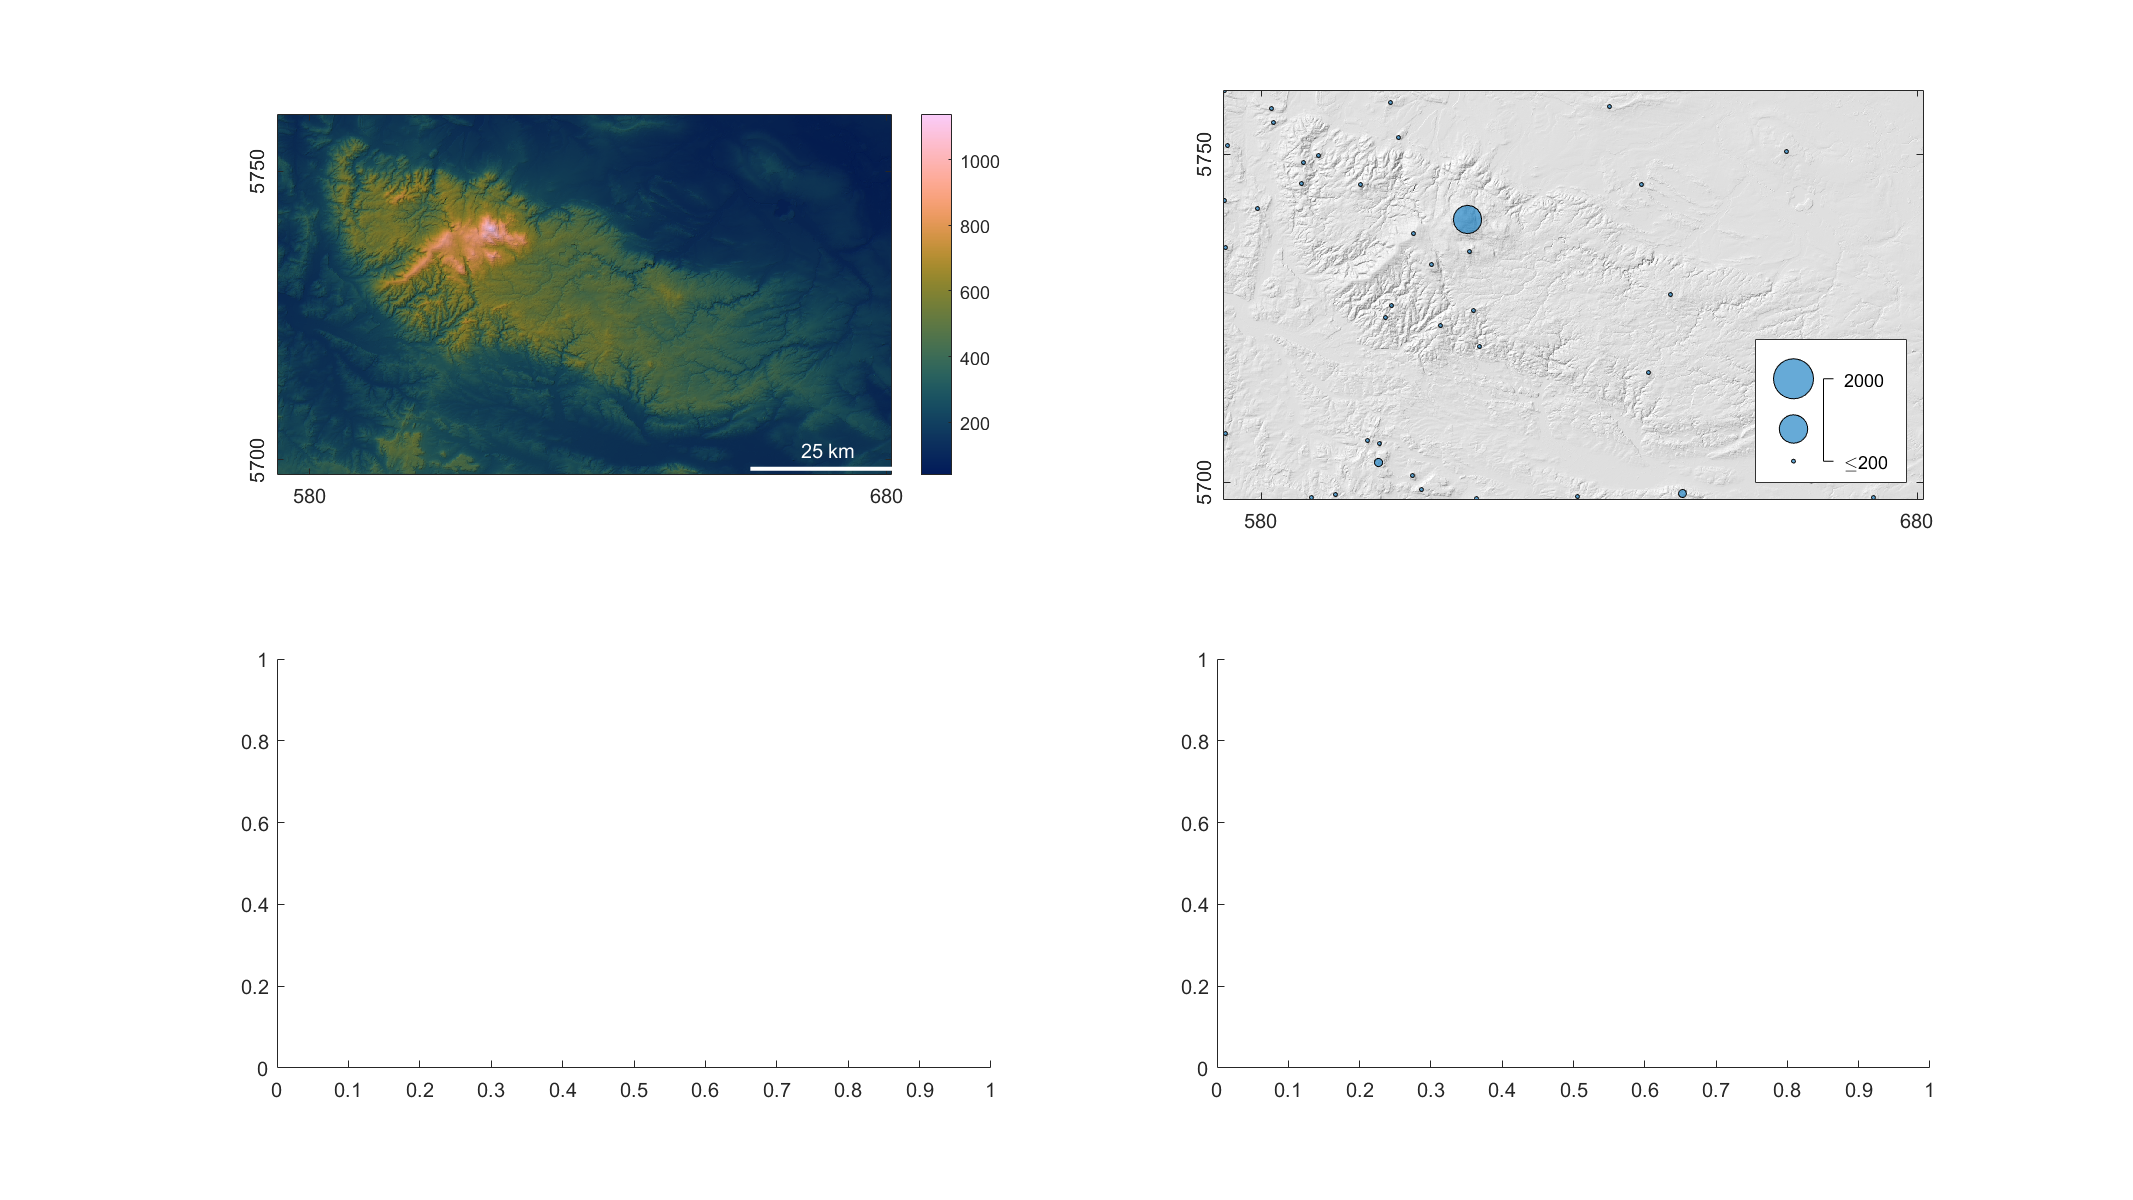

h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 

subplot(2,2,1)
imageschs(DEM,[],'colormap',ttscm('batlow'),'ticklabels','nice','tickstokm',true)
SB = ScaleBar('color','white','xyunit','km','displayunit','km');

subplot(2,2,2)
[x,y,p] = prominence(DEM,100);
imageschs(DEM,[],'colormap',[1 1 1],'colorbar',false,'ticklabels','nice','tickstokm',true);
hold on
h = bubblechart(x/1e3,y/1e3,p);
h.MarkerEdgeColor = 'k';
bubblelim([200 2000])
bubblesize([2 20])
bubblelegend('location','southeast')
hold off

subplot(2,2,3)
% chose some topographic metric that you're interested, calculate and plot
% it along with the others


subplot(2,2,4)

% chose some topographic metric that you're interested, calculate and plot
% it along with the others

subplotlabel(h,'A')

Error using ishold
Using hold with matlab.graphics.chart.primitive.BubbleChart is not supported.

Error in subplotlabel (line 190)
                if ishold(ax)

### OPTIONAL: PPS

The analysis of point patterns is a big field in statistics. For us Geomorphologists, observations are often tied to a river network. For instance, knickpoints in stream profiles, stream gauges, beaver dams, etc. This is where PPS comes into play. A PPS is a point pattern stored on a stream network and TT provides several tools to perform stastistical anaylsis of these patterns. For example, are my points distributed randomly along the stream or do they follow a pattern with resepect to some other variable? Also, PPS contains several tools for simple plotting, exporting etc. In the next section, I'll introduce the use of PPS in the context of knickpoint analysis of stream networks.

Unfortunately, the autmated knickpoint analysis for the Hartz does not work so well and the results are not as nice as I hoped for. This is why we're gonna do a slightly modified version of example 'bigtujunga' from Schwanghart (2021) instead. In this example, we'll look at knickpoints in the TT standard catchment Big Tujunga in California.

clear
DEM = GRIDobj('srtm_bigtujunga30m_utm11.tif');
FD  = FLOWobj(DEM);
S   = STREAMobj(FD,'minarea',500); 
S   = modify(S,'distance',11800);
S   = klargestconncomps(S);  % select largest river basin within DEM

% lets calculate the chi
A = flowacc(FD);
chi = chitransform(S,A,'mn',0.5);

### mapping knickpoints

TT has a really cool tool, the knickpointfinder. This tool will search for breaks in your stream profiles. The algorithm assumes a river should have a stricly concave profile. In locations where the offset between the actual and concave profile becomes large, convexities (kickpoints) exist and the algorithm will fit a different segment on the other side of this slope break. 

The kickpointfinder requires a threshold value for the offset between actual and modelled concave profile that should result in a knickpoint. This tolerance is a bit hard to gauge. It should definitely be larger than the error of your DEM data. My personal approach is trial and error. For example, I will run the knickpointfinder with different tolerance values and check visually in the chi-plots, if I would have picked similar points. I've used values between 20-100m in the past.

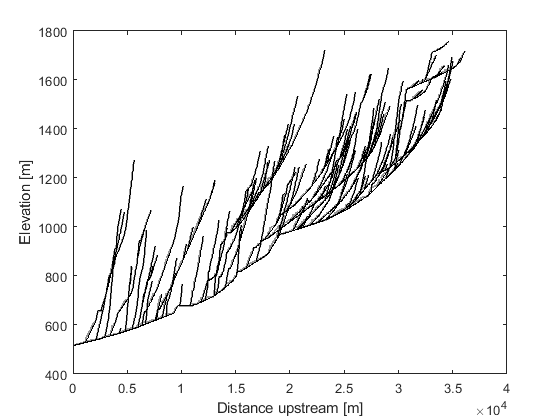

[~,kp] = knickpointfinder(S,DEM,'tol',20,'split',false,'verbose',false);

The black lines are the fitted profiles and the gray in the brackground are the observed river elevations. Ivestigate the kp variable. It's a strcuture with x,y,z coordinates but also the stream distance and linear grid indices. We can take these knickpoints and turn them into a PPS. All we need to do, is to use the PPS command, provide a STREAMobj and a point pattern (in this case linear indices of knickpoints). Let's also add some smoothed river elevations.

Z = smooth(S,DEM);
P = PPS(S,'pp',kp.IXgrid,'z',Z);

Cool! Now, let's see what PPS has to offer. Try the plain 'plot' command and see what happens.

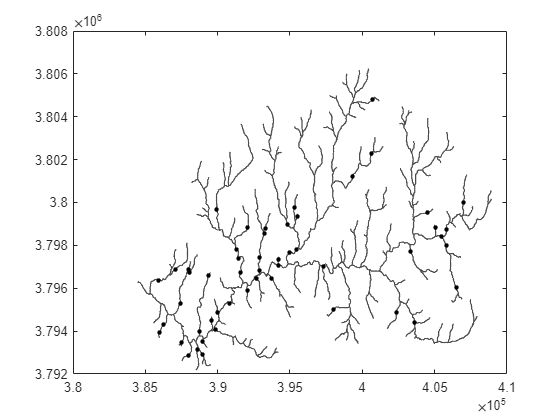

plot(P)

Another cool simple plot command is 'plotdz', which will plot the stream profiles with the knickpoints directly on top. One can specify 'SizeData' or 'color' for the knickpoint makers.

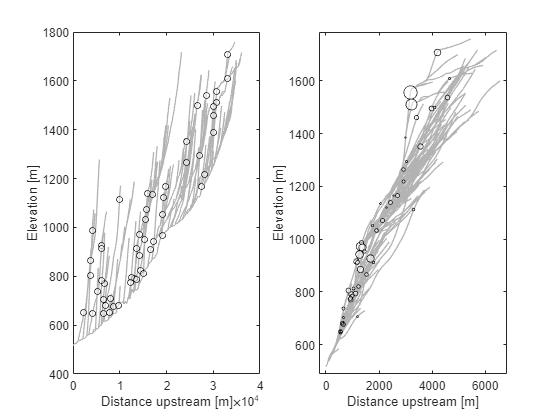

subplot(1,2,1)
plotdz(P)
subplot(1,2,2)
plotdz(P,'distance',chi,'SizeData',kp.dz)

I've mentioned earlier that the idea behind PPS is to conduct stastical analysis of point patterns and for instance investigate their spatial distribution. For example, the density of points along a stream network can be calculated and plotted:

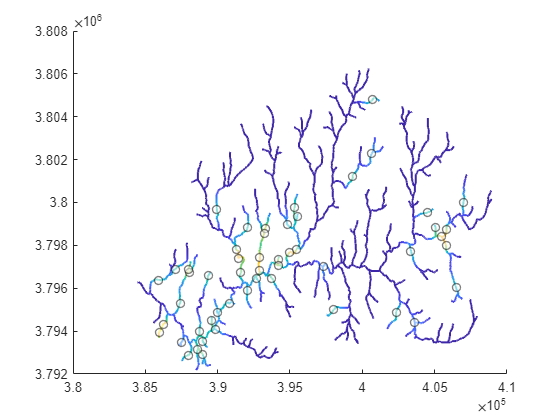

den = density(P);
figure
plotc(P,den)

You can also do a similar density estimate with respect to a some other variable, e.g. elevation, chi, distance from outlet, etc. For this, you can use the function 'rhohat'. Let's try and see if there is an elevation clustering of the knickpoints.

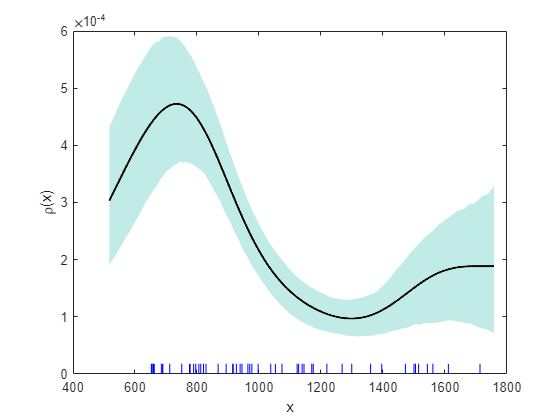

figure
rhohat(P,'covariate',DEM)

As you can see, 'rhohat' automatically computes confidence intervals for the estimate, which are based on bootstrap sampling. The curve you see is a density estimate of your knickpoints with respect to elevation. The light blue lines at the bottom are the actual elevation-locations of kickpoints from which the density esimtate is calculated.

Ok, lets switch gears up a bit and use PPS to make a cool figure with the kickpoints locations on the DEM, scaled by their knickpoint height (a measure of kickpoint prominence). At the bottom of the same figure, let's plot the river elevation profile on the left and the chi-elevation profile on the right.

We can add knickpoint density estimates to the lower two plots. On the left, we can add estimates based on the distance from the outlet, on the right one we can check if knickpoints cluster at same chi-values (which is what we would expect to see from an external pertubation). Moreover, we have the option of weigthing knickpoints by their height (or importance) for this density estimate. So, Let's do both, with and without weighting!

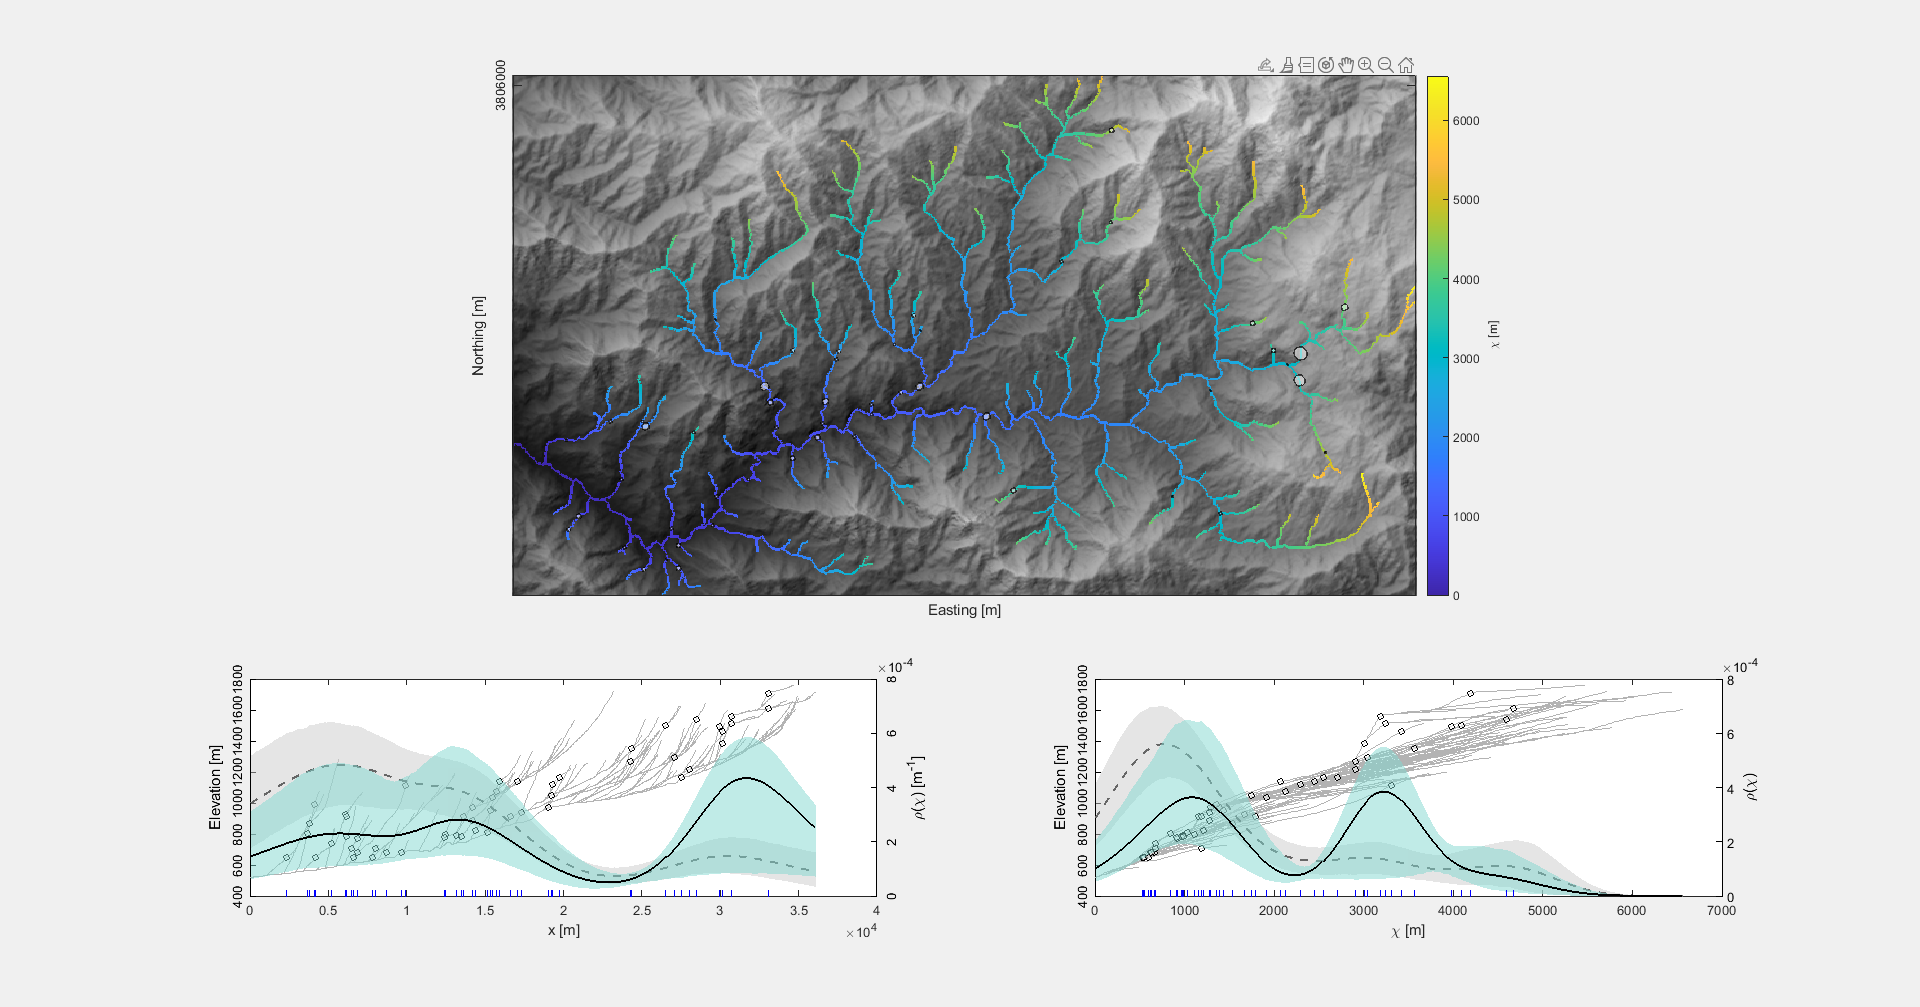

h = figure;
set(h,'Units','normalized','Position',[0 0 1 1],'visible','on'); 

%% Map ------------------------------------------------
subplot(3,2,1:4);
imageschs(DEM,[],'colormap',gray,'colorbar',false,'usepermanent',true,...
    'ticklabels','nice')          % draw DEM in grayscale
hold on
plotc(P.S,chi,'LineWidth',2)      % plot river colored by chi
h = colorbar;
h.Label.String = '\chi [m]';         

plotpoints(P,'SizeData',kp.dz,'MaxSize',500,...
    'MarkerFaceColor','w','LineWidth',1.2,...
    'MarkerEdgeAlpha', 0.7)       % plot knickpoints scales by knickpoint height
xlabel('Easting [m]')
ylabel('Northing [m]')
setextent(S,gca)
hold off

%% Density estimates (distance from outlet) -----------------
ax(1) = subplot(3,2,5);
plotdz(P)                        % plot river profiles and knickpoints
ytickangle(90) 
yyaxis right
ax = gca;
ax.YColor = 'k';

bw = 3000;                       % bandwidth of kernel estimate
% Unweighted
r1 = rhohat(P,'bandwidth',bw,'FaceColor',[.8 .8 .8],...
    'LineStyle','--','Color',[.4 .4 .4],'name','x');  % do knickpoints cluster at certain distance?
% Weighted
r2 = rhohat(P,'bandwidth',bw,'weights',kp.dz.^2,...
    'LineStyle','-','Color','k','name','x'); % do knickpoints cluster at certain distance; results weigthed by kp height
xlabel('x [m]')
ylabel('\rho(\chi) [m^{-1}]')
ytickangle(90)

% Density estimates (CHI) -----------------
ax(1) = subplot(3,2,6);        
plotdz(P,'distance',chi)       % plot river chi-profiles and knickpoints
ytickangle(90)
yyaxis right

ax = gca;
ax.YColor = 'k';

%% Density estimates (chi)
bw = 400;
r3 = rhohat(P,'covariate',chi,'bandwidth',bw,'FaceColor',[.8 .8 .8],...
    'LineStyle','--','Color',[.4 .4 .4],'name','\chi');   % do knickpoints cluster at certain chi-value?
r4 = rhohat(P,'covariate',chi,'bandwidth',bw,'weights',kp.dz.^2,...
    'LineStyle','-','Color','k','name','\chi'); % do knickpoints cluster at certain chi-value; weighted by kp height
xlabel('\chi [m]')

Now, let's try and interpret this plot. On the map, we see most knickpoints are located in the lower part of the catchment, with a secondary cluster in its headwaters. This can also be seen in lot (b). The grey estimate (non-weighted) is highest near the outlet and has a mini-secondary peak in the headwaters. The weighted density estimate in blue accentuates the upper catchment knickpoints, because they are more prominent. However, you also see that the upper peak has a huge confidence interval because there are only few points. We can see a similar picture in chi-space on the right. Two distinct clusters of knickpoints suggest two waves of incision, probably related to increased fault slip on the range-bounding fault (Wobus et al., 2006). If we had an estimate of fluvial erodibility, we could model the knickpoint propagation and estimate the two times when fault slip increased. 

As a last step, let's calculate where in the catchment one would expect so see knickpoints based on this chi estimate of knickpoint clustering. Basically, we have a density estimate now, for all chi-values, which we can plot onto the stream network again and identify areas, where this falls together with lots of knickpoints, and where it doesn't.

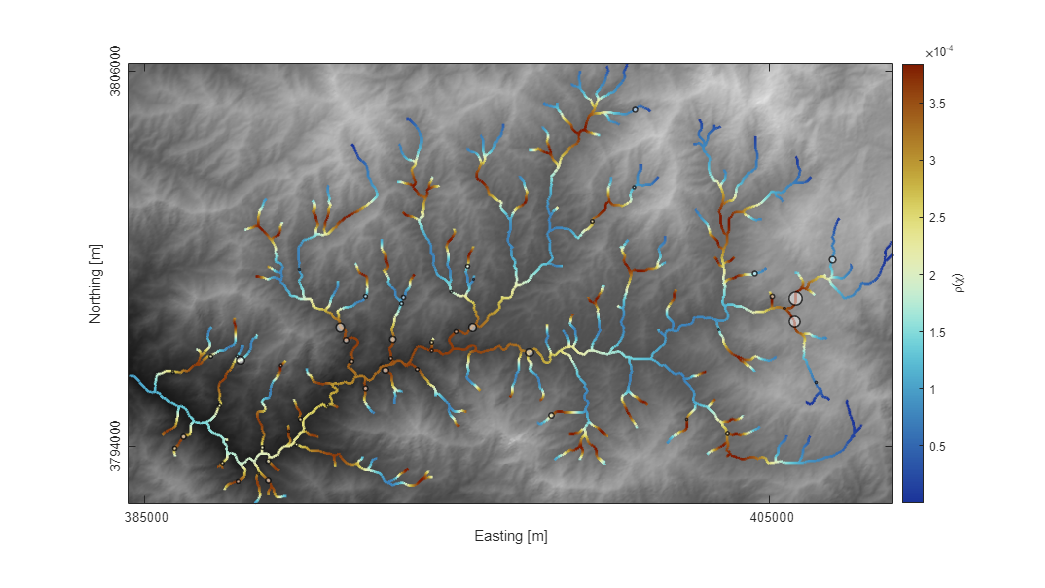

h = figure;
set(h,'Units','normalized','Position',[0 0 1 1]); 

imageschs(DEM,[],'colormap',gray,'colorbar',false,'usepermanent',false, ...
    'exaggerate',0.3)
hold on
plotc(S,r4.rho,'linewidth',2)
h = colorbar;
colormap(flipud(ttscm('roma')))
h.Label.String = '\rho(\chi)';
plotpoints(P,'SizeData',kp.dz,'MaxSize',500,'MarkerFaceColor','w','LineWidth',1.2,...
    'MarkerEdgeAlpha',0.7)
hold off
xlabel('Easting [m]')
ylabel('Northing [m]')
setextent(S,gca)
niceticks

In the lower catchment part, knickpoints seem to mostly lie within the high density estimate. For the upstream high density regions, only a few knickpoint in the east match. The tributaries in the north lack the high-chi knickpoints. Why is this the case? I don't know. I'll let you speculate ;)